# Visualizing GPS data from Matlab Mobile

**Joan Vazquez Molina, May 2020**

The goal of this live script is to produce some first visualizations of GPS data from Matlab Mobile.

## Introduction

It is COVID-19 time, so I just went to the bakery and back home.

Data has been logged using Matlab Mobile. It consists of timetables of:

- Position (latitude, longitude, altitude, speed, course, horizontal accuracy).

- Acceleration (X, Y, Z). *When the device lies flat on a surface, the acceleration value along the Z axis is +9.81.*

- Magnetic field  (X, Y, Z).

- Orientation (X, Y, Z).

- Angular velocity (X, Y, Z).

Sampling rate has been set to 10Hz.

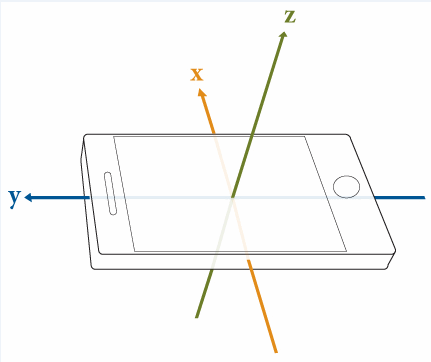

## Plot Leuven walk on a map

Based on: [Acquire GPS Data from Your Mobile Device and Plot Your Location and Speed on a Map](https://www.mathworks.com/help/matlabmobile_android/ug/acquire-gps-data-and-plot-your-location-and-speed-on-a-map.html)

Requires:

- [MATLAB Mobile App](https://mathworks.com/products/matlab-mobile.html): to log data from smartphone sensors (free).

- [Mapping Toolbox](https://mathworks.com/products/mapping.html)

### Load Data

For this section we will only need latitude, longitude, time and speed.

data = load('measurement\sensorlog_20200508_145245.mat')

data = struct with fields:
       Acceleration: [9223×3 timetable]
      MagneticField: [9161×3 timetable]
        Orientation: [9160×3 timetable]
    AngularVelocity: [9161×3 timetable]
           Position: [917×6 timetable]


lat = data.Position.latitude;
lon = data.Position.longitude;
t = data.Position.Timestamp;
spd = data.Position.speed;

### Bin speeds into color values

% Create bins for speed values
nBins = 10;
binSpacing = (max(spd) - min(spd))/nBins; 
binRanges = min(spd):binSpacing:max(spd)-binSpacing; 

% Add an inf to binRanges to enclose the values above the last bin.
binRanges(end+1) = inf;

% |histc| determines which bin each speed value falls into.
[~, spdBins] = histc(spd, binRanges);

### **Split Latitude and Longitude Data by Speed**

lat = lat';
lon = lon';
spdBins = spdBins';

% Create a geographical shape vector, which stores the line segments as
% features.
s = geoshape();

for k = 1:nBins
    
    % Keep only the lat/lon values which match the current bin. Leave the 
    % rest as NaN, which are interpreted as breaks in the line segments.
    latValid = nan(1, length(lat));
    latValid(spdBins==k) = lat(spdBins==k);
    
    lonValid = nan(1, length(lon));
    lonValid(spdBins==k) = lon(spdBins==k);    

    % To make the path continuous despite being segmented into different
    % colors, the lat/lon values that occur after transitioning from the
    % current speed bin to another speed bin will need to be kept.
    transitions = [diff(spdBins) 0];
    insertionInd = find(spdBins==k & transitions~=0) + 1;

    % Preallocate space for and insert the extra lat/lon values.
    latSeg = zeros(1, length(latValid) + length(insertionInd));
    latSeg(insertionInd + (0:length(insertionInd)-1)) = lat(insertionInd);
    latSeg(~latSeg) = latValid;
    
    lonSeg = zeros(1, length(lonValid) + length(insertionInd));
    lonSeg(insertionInd + (0:length(insertionInd)-1)) = lon(insertionInd);
    lonSeg(~lonSeg) = lonValid;

    % Add the lat/lon segments to the geographic shape vector.
    s(k) = geoshape(latSeg, lonSeg);
    
end

### **Create a Web Map and Route Overlay**

wm = webmap('Open Street Map');

% Add route
colors = autumn(nBins);
wmline(s, 'Color', colors, 'Width', 5);

% Add icons
icon(1).name = 'Home';
icon(1).Lat = 50.879581;
icon(1).Lon = 4.713190;
icon(1).filename = 'icon\home.png';
wmmarker(icon(1).Lat, icon(1).Lon, 'FeatureName', icon(1).name, ...
    'Icon', icon(1).filename, 'IconScale', 2);

icon(2).name = 'Bakery';
icon(2).Lat = 50.882139;
icon(2).Lon = 4.713883;
icon(2).filename = 'icon\bread.png';
wmmarker(icon(2).Lat, icon(2).Lon, 'FeatureName', icon(2).name, ...
    'Icon', icon(2).filename, 'IconScale', 2);

% Zoom in
wmzoom(17);

### 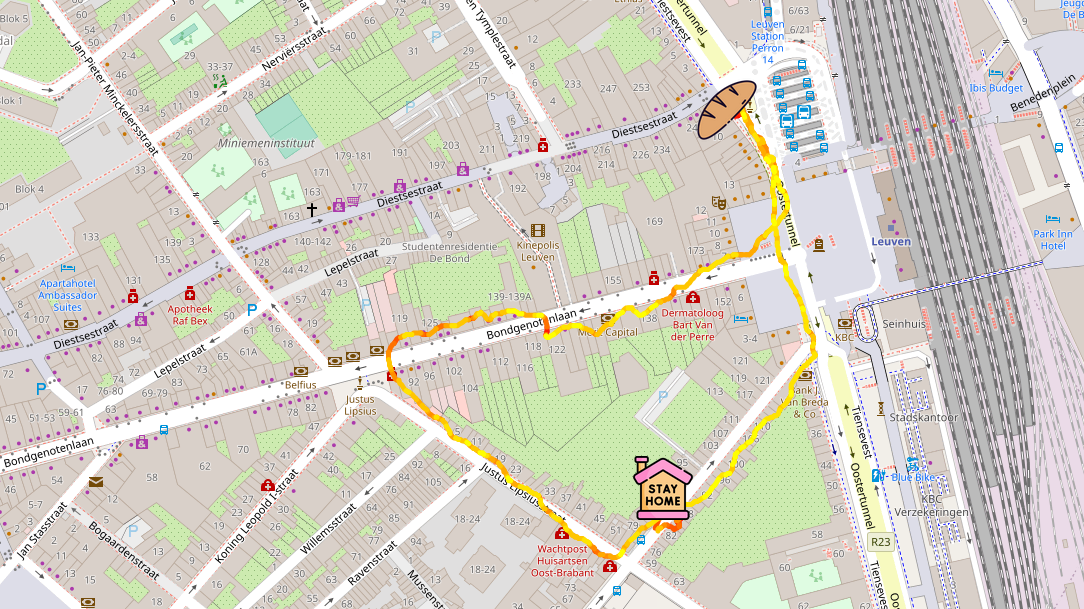

### Discussion

- While the path is clear, the accuracy does not seem very good. For example, in Bondgenotenlaan, I did not cross the street twice. And in Maria-Theresiastraat, I was walking on the other side of the road.

## Accuracy: descriptive statistics

First, check / create *out* folder to store output figures:

if ~exist('out', 'dir')
       mkdir('out')
end

How long was the walk? Subtracting two *datetimes* gives a *duration* of ~15min

t(end) - t(1)

ans = duration
   00:15:16


Was the GPS sampling rate actually 10Hz? No. For the rest of sensors it was 10Hz, as specified, but for the GPS data it was only 1Hz for some reason.

mean(diff(t))

ans = duration
   00:00:01


Let's examine the horizontal accuracy data. It has a curious format: the data is discrete up to 50m, and continuous from there.

hacc = data.Position.hacc;
tabulate(hacc)

   Value    Count   Percent
       5      345     37.62%
      10      498     54.31%
      30       35      3.82%
      50       12      1.31%
  50.446        1      0.11%
  50.675        1      0.11%
  50.973        1      0.11%
  50.994        1      0.11%
  51.279        1      0.11%
  51.606        2      0.22%
  51.749        1      0.11%
   51.96        1      0.11%
  52.184        1      0.11%
  52.398        1      0.11%
   52.58        1      0.11%
  53.237        1      0.11%
  53.299        1      0.11%
  53.437        1      0.11%
  54.215        1      0.11%
  54.244        1      0.11%
  54.667        1      0.11%
  54.987        1      0.11%
  55.235        1      0.11%
  55.442        1      0.11%
  56.118        1      0.11%
  56.799        1      0.11%
  56.975        1      0.11%
   57.87        1      0.11%
  60.214        1      0.11%
  78.129        1      0.11%


DIscreteness suggests to use a *stairs* plot instead of a regular line. The accuracy was 5m or 10m most of the time, with short spikes up to 80m. It would be interesting to correlate the loss of accuracy spikes to physical events, but it is beyond the scope of this report.

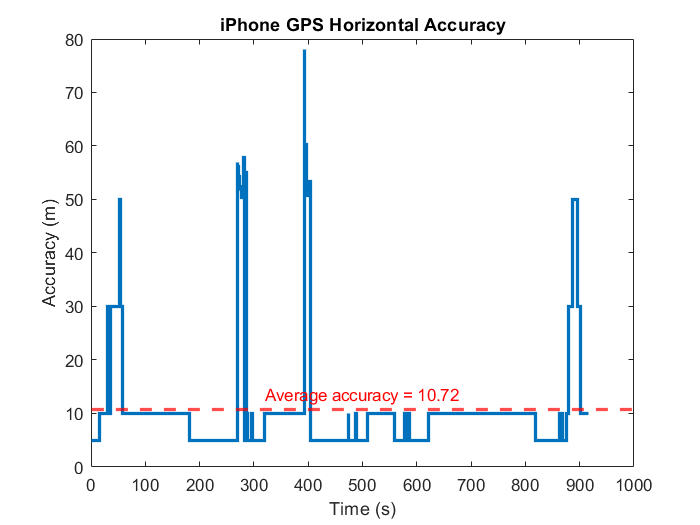

figure('Name', 'Horizontal accuracy: stairs')
stairs(hacc, 'LineWidth',2)
yline(mean(hacc), 'r--', ['Average accuracy = ' num2str(round(mean(hacc),2))], ...
    'LineWidth', 2,...
    'LabelHorizontalAlignment', 'center');
title('iPhone GPS Horizontal Accuracy')
xlabel('Time (s)')
ylabel('Accuracy (m)')
savefig('out\hacc_stair.fig');
saveas(gcf, 'out\hacc_stair.png')

It is useful to visualize the same data in a histogram. The bins are defined to suit this particular sample of discrete + continuous data.

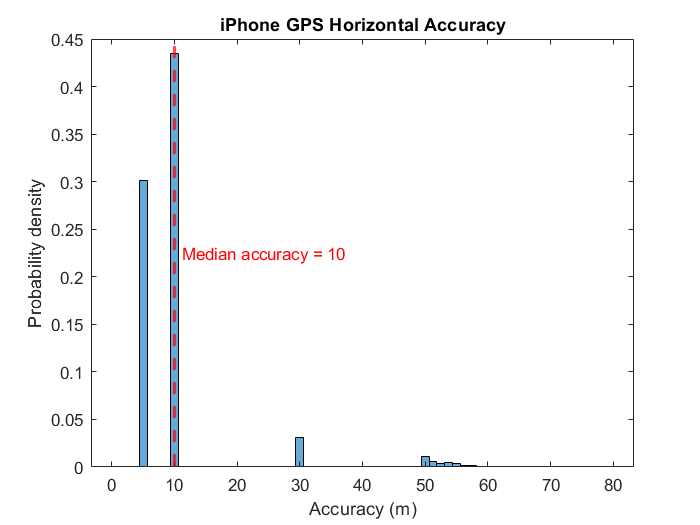

figure('Name', 'Horizontal accuracy: histogram')
bins = (0:1.25:max(hacc)+1.25) + 1.25/2;
histogram(hacc, bins, 'Normalization', 'pdf')
xline(median(hacc), 'r--', ['Median accuracy = ' num2str(round(median(hacc),2))], ...
    'LineWidth', 2,...
    'LabelVerticalAlignment', 'middle',...
    'LabelOrientation', 'horizontal');
title('iPhone GPS Horizontal Accuracy')
xlabel('Accuracy (m)')
ylabel('Probability density')
savefig('out\hacc_hist.fig');
saveas(gcf, 'out\hacc_hist.png')

## Conclusion

- It is very easy to acquire GPS and inertial data from a smartphone using Matlab Mobile.

- The median horizontal accuracy was 10m, which is enough for some basic applications like plotting a city walk on a map.

- Although the sampling rate was set to 10Hz, GPS data was only logged at 1Hz.